# QPSK Transmitter Using Software-Defined Radio

This example shows the implementation of a QPSK transmitter using a software-defined radio (SDR), which modulates and transmits indexed "Hello world" messages at specified center frequency and a bit rate of 1 Mbps. In this example, the transmitter generates a message using ASCII characters, converts these characters to bits, and appends a Barker code at the beginning for receiver frame synchronization. This data is then QPSK modulated and filtered with a square root raised cosine filter. You can transmit the filtered QPSK symbols over the air using SDR. You can demodulate the transmitted message using the QPSK Receiver Using Software-Defined Radio example.

## **Required Hardware and Software**

To run this example, you need one of these USRP or ADALM-PLUTO radios and the corresponding hardware support package.

- USRP™ N2xx series or B2xx series radio and Communications Toolbox Support Package for USRP Radio. For more information, see [USRP Radio](docid:comm_doccenter#mw_de5fc03d-bc6e-471f-8da6-5e93b9b65012) and [Supported Hardware and Required Software](docid:usrpradio_ug#buzc7a6-1). 

- USRP™ N3xx series or X series radio and Wireless Testbench Support Package for NI USRP Radios. For more information, see [Supported Radio Devices](docid:wt_gs#mw_74eb94c7-dcbc-40dc-8a56-cc7bc0124002) (Wireless Testbench).

- ADALM-PLUTO radio and Communications Toolbox Support Package for Analog Devices® ADALM-PLUTO Radio. For more information, see [ADALM-Pluto Radio](docid:comm_doccenter#mw_0e7ad01a-dc12-4f4d-bd42-54dc112c2e1d). 

## Initialization

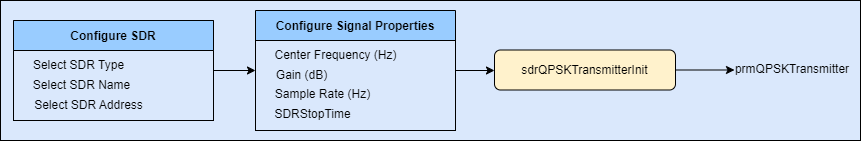

### Select Radio

Select the required radio SDRName from the `availableRadios`. For more information regarding discovery of radios see findsdru and findPlutoRadio for USRP and PLUTO radios respectively.

sdrType = "USRP";
availableRadios = helperFindRadios(sdrType);

Checking radio connections ...

    SDRName    SDRType    SDRAddress
    _______    _______    __________

    "B210"     "USRP"     "30F597A" 
    "B200"     "USRP"     "F5BC9E"  



SDRName = "B200";
SDRAddress = 'F5BC9E';

Run `clear all` whenever the SDR is modified.

### Initialize Transmitter Parameters

`sdrQPSKTransmitterInit.m` script initializes the simulation parameters and generates the structure `prmQPSKTransmitter`.

sampleRate         = 1000000;  % Sample rate of transmitted signal
SDRGain            = 35;  % Set radio gain
SDRCenterFrequency = 915000000;  % Set radio center frequency
SDRStopTime        = 10;  % Radio transmit time in seconds

% Transmitter parameter structure
prmQPSKTransmitter = sdrQPSKTransmitterInit(SDRName, SDRAddress, sampleRate, SDRCenterFrequency, ...
    SDRGain, SDRStopTime)

prmQPSKTransmitter = struct with fields:
               ModulationOrder: 4
                 Interpolation: 2
                    Decimation: 1
                            Fs: 1000000
                          Rsym: 500000
                          Tsym: 2.0000e-06
                    BarkerCode: [1 1 1 1 1 -1 -1 1 1 -1 1 -1 1]
                  BarkerLength: 13
                  HeaderLength: 26
                       Message: 'Hello world'
                 MessageLength: 16
               NumberOfMessage: 100
                 PayloadLength: 11200
                     FrameSize: 5613
                     FrameTime: 0.0112
                 RolloffFactor: 0.5000
                 ScramblerBase: 2
           ScramblerPolynomial: [1 1 1 0 1]
    ScramblerInitialConditions: [0 0 0 0]
        RaisedCosineFilterSpan: 10
                   MessageBits: [11200×1 double]
                      Platform: "B200"
                       Address: 'F5BC9E'
                       IsPluto: 0
             

**Note: **To achieve a successful transmission, ensure that the specified center frequency of the transmitter system objects is within the acceptable range of your respective  RF cards.

## Code Architecture

[image: A flowchart titled runSDRQPSKTransmitter which depicts the process of a QPSK Transmitter. It begins with an arrow pointi]

The function `runSDRQPSKTransmitter` implements the QPSK transmitter using two System objects,

- `QPSKTransmitter` for generation of transmission signal.

- Either` comm.SDRuTransmitter` for USRP or `comm.SDRTxPluto` for ADALM-PLUTO.

### **QPSK Transmitter**

The transmitter includes the **Bit Generation**, **QPSK Modulator**, and **Raised Cosine Transmit Filter** objects. The **Bit Generation** object generates the data frames. The Barker code is sent on both in-phase and quadrature components of the QPSK modulated symbols. This is achieved by repeating the Barker code bits twice before modulating them with the QPSK modulator.

The remaining bits are the payload. The payload contains 100 'Hello world ###' messages, where '###' is an increasing sequence of '000', '001', ... '099' in binary forms. The number of messages is tunable via the initialization file, namely transmitter initialization file. Please make corresponding changes in the receiver initialization file, receiver initialization file. The payload is then scrambled to guarantee a balanced distribution of zeros and ones for the timing recovery operation in the receiver object. The scrambled bits are modulated by the **QPSK modulator** (with Gray mapping). The **Raised Cosine Transmit Filter** upsamples the modulated symbols by two, and has roll-off factor of 0.5. The output rate of the **Raised Cosine Filter** is set to be 1 M samples per second with a symbol rate of 0.5 M symbols per second.

### **USRP/PLUTO Transmitter**

The host computer communicates with the USRP radio using `comm.SDRuTransmitter` and with the ADALM-PLUTO radio using `comm.SDRTxPluto` System object.

## Execution

As already mentioned, you can check the correct data transmission by running the QPSK Receiver with Software-Defined Radio example while running the transmitter script.

underruns = runSDRQPSKTransmitter(prmQPSKTransmitter);
fprintf('Total number of underruns = %d.\n', underruns);

Total number of underruns = 0.


**Note:** Before running the example, first connect the selected platform, `SDRName`, to the computer and turn it on.

## Troubleshooting

- The gain behavior of ADALM-PLUTO and different USRP  RF cards varies considerably. Thus, the gain setting in the transmitter and receiver defined in this example may not be well suited for your RF cards. If the message is not properly decoded by the receiver object, you can vary the gain of the source signals in the **SDR Transmitter** and **SDR Receiver** System objects by changing the **SDRGain** value.

- A large relative frequency offset between the transmit and receive radios can prevent the receiver functions from properly decoding the message. If that happens, you can determine the offset by sending a tone at a known frequency from the transmitter to the receiver, then measuring the offset between the transmitted and received frequency, then applying that offset to the center frequency of the respective receiver System object.

## Helper Functions

- `helperFindRadios.m`

- `sdrQPSKTransmitterInit.m`

- `runSDRQPSKTransmitter.m`

- `QPSKTransmitter.m`

- `QPSKBitsGenerator.m`

*Copyright 2012-2025 The MathWorks, Inc.*